## DKE Introduction to Bioinformatics 2022

# **Assignment 2**

*Elena Perego - i6238107*

### Sequence Allignment

Another friend of Peter’s studies unicellular microalgae (symbiodinium necroappetens) which also have a RING1 protein, but it is much longer than the human version.  The accession number of this protein is CAE7901930. How close is the algae version to the human protein?  Explain your results.

Make a new livescript with your working and explanations for this part and submit this file to the assignment on canvas. 

### **Allignment of the two proteins**

First, the data of the two versions of the protein is retrieved

data_human = getgenpept('CAA78389','SequenceOnly',true)

data_human = 'MDGTEIAVSPRSLHSELMCPICLDMLKNTMTTKECLHRFCSDCIVTALRSGNKECPTCRKKLVSKRSLRPDPNFDALISKIYPSREEYEAHQDRVLIRLSRLHNQQALSSSIEEGLRMQAMHRAQRVRRPIPGSDQTTTMSGGEGEPGEGEGDGEDVSSDSAPDSAPGPAPKRPRGGGAGGSSVGTGGGGTGGVGGGAGSEDSGDRGGTLGGGTLGPPSPPGAPSPPEPGGEIELVFRPHPLLVEKGEYCQTRYVKTTGNATVDHLSKYLALRIALERRQQQEAGEPGGPGGGASDTGGPDGCGGEGGGAGGGDGPEEPALPSLEGVSEKQYTIYIAPGGGAFTTLNGSLTLELVNEKFWKVSRPLELCYAPTKDPK'

data_microalgae = getgenpept('CAE7901930','SequenceOnly',true)

data_microalgae = 'MASFAPLRRSRGLALLVLSLPLCCFVSAWGTARGRRVEYQARHAAPEPAEPELASPAWEESAQVVLEIVEDSTKEDALDWLQAGYAWTAKSRRFWRKLRSPMPPEPEAVRRTARWLQDKGLAQKAWVRRFPEVLGLSVEDLEEGRSTAPSYLKSEDTYNKAIKSNPTLLGKNYDCLQEHESCQGRCSRCWNTTDAEQSEQYTLCGCLGFLGGLSILENIGPLKLRAGSSSGTVSGLSSISGSSYQAAMKHALLLLALPAHATQISTEDPALLSDEQASLREEDEWRPSAQATFPRPSYGNGWSPWSGNPGSLPGGPAAHLPYQAVPRVPAPPPAGTFPKVAVSSAASGAGPNNLKEAEAETKKFFEIEEMVAKETGLPLNSSEAAQKEEEEKAEAKEVEEEEEEERFDALYAGIALVILLAAGGTFYFHRWSQDKPKPGEALGAAAPSSPEADPKAPGPAEAEAKAATGRMKRKLLQLQVLILLSPLSEGPLSCQWGERWPLPDPSPSEGAMGKKRKAEFEPPPVNLDALPPLEEGILRFEFTLEEKGALGVRFSGGSPPMILSVAPDSFASKKGIPVNYEVHAINGLALVQQNQQRVMHFLKSRPVVLDVRPLGWKPPEKMKELKRRQQQEEAEQKAKMAVEKKRREQDGWKVEMHSEEIQQFNADVRQVFSSVFSACTWLSKPNERSPQLVPQKPLPLGQNQLRVCEELERLGLLKASPLPSPFVVAFHELLSSPVGGECSCGAMGDLPFSLAALLNSGAGALGPAREGGTITLLTLPGRGLVGAAITPSGSEPGFPLPLGLLQSLGGQVSRVPVAAEEDAADALGGIMRMMMEQMAQIAMQRSMEESGPKVPPASERVRDALPRVVVTKEDLLDATNSKCSVCLEDYRPGVRATRMLCGHLFCTGCIREWLREANTCPVCRYELATDCEDFESGRRTRMSGRIVRLRAAELRMLRISELRRLMDALGVSGEGCLERAD

Then, to understand if they are similiar, they need to be align either locally or globally. To understand which one, a dot plot of the two sequences is shown.

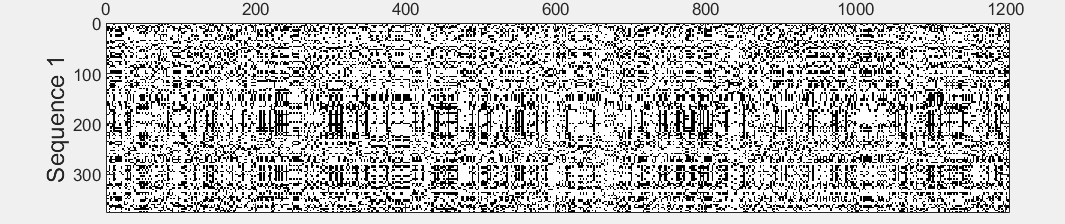

seqdotplot(data_human,data_microalgae)

Based on the plot, a local alighnment is the best option for two reasons. First, it can be noticed that one sequence, the unicellular microalgae, is way bigger than the other, therefore, an accurate global matching will be difficult. Second, there is no neat diagonal showing any matching. 

Nevertheless, the scoring space and the winning path for both allignments is shown to actually see the difference in score between them. It is important to notice that the scoring matrix is changed from the default, BLOSUM50, to BLOSUM30. This is done because, based on the previous findings, the two proteins are very different, therefore it does not make sense to use BLOSUM50, which assumes that the two sequences are around 50% similiar. Among the suggested BLOSUM scoring matrices, BLOSUM30 was the lowest suggested, which better agrees with the similiarity between the two sequences.

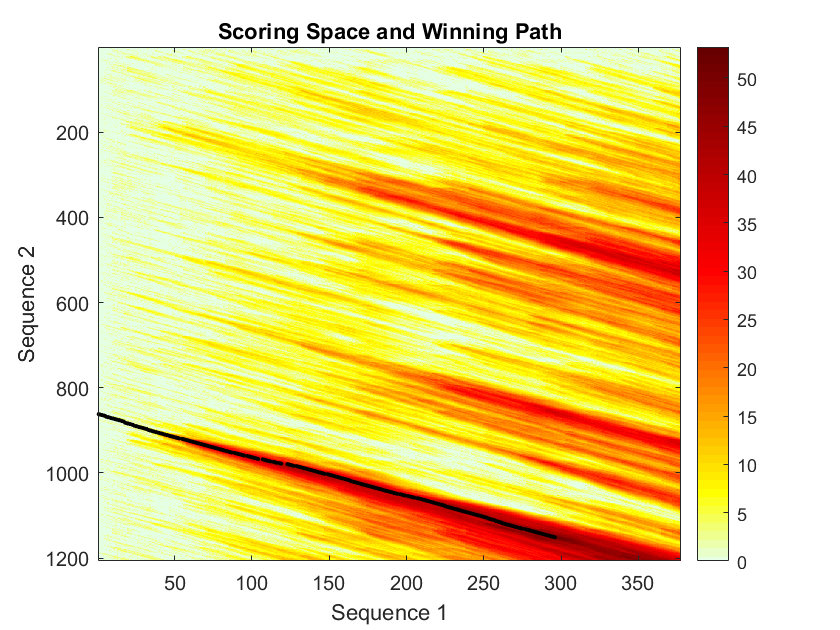

score_local = 53.2000

alignment_local = 3×306 char array
    'MDGTE-IAVSPRSLHSEL--MCPICL-DMLKNTMTT-KECLHRFCSDCIVTALRSGNKECPTCRKKLVSKRSLRPDPNFDALISKIYPSREEYEAHQDRVLIRLSRLHNQQALSSSIEEGLRMQAMHRAQRVRRPIPGSDQTTTMSGGEGEPGEGEGDGEDVSSDSAP-DSAPGPAPKRPRGGGAGGSSVGTGGGGTGGVGGGAGSEDSGDRGGTLGGGTLGPPSPPGAP-SPPEPGGEIELVFRPHPLLVEKGEYCQT-RYVKT-TGNA-TVDHLSKYLALRIALERRQQQEAGEPGGPGGGASD'
    ':|::: ::|:: :| :::  :| :|| |  :::::| : | | ||: ||   ||::|  ||:|| :|::: :  ::     : ::|:  |:: |    |:   | ||::  ||: |  ||: ::   ||  | |:::|:  : ::   ::|: :   | :|::  : |   :  : :: |    :  |:      :: :: : ||    |: : |    : | :  |: | :::||:  :  :| | :   |:||  :: :: :| :| :  ::  ::  | | | |  :::    ||::: :::|'
    'RDALPRVVVTKEDLLDATNSKCSVCLEDYRPGVRATRMLCGHLFCTGCIREWLREANT-CPVCRYELATDCEDFESGRRTRMSGRIVRLRAA-ELRMLRI-SELRRLMD--ALGVSG-EGC-LE---RADLV-RHLEGAPDVEVAPELSAEK-KFRYDLQDLEQLDLPLLRNLMERHRVPFDLEEDLSEDDERRVALRSF-ADAG-WMRGA-SKTPPKPSEGAKQMPARPENTTEPAQTTTAAFVPSTDAGESGESGESEMRSETPSGESCEAKSRAAGKAARPA-EPPPARRRPRPGAKAEAKAD'


[score_local,alignment_local] = swalign(data_human, data_microalgae,ScoringMatrix='BLOSUM30',Showscore=true)

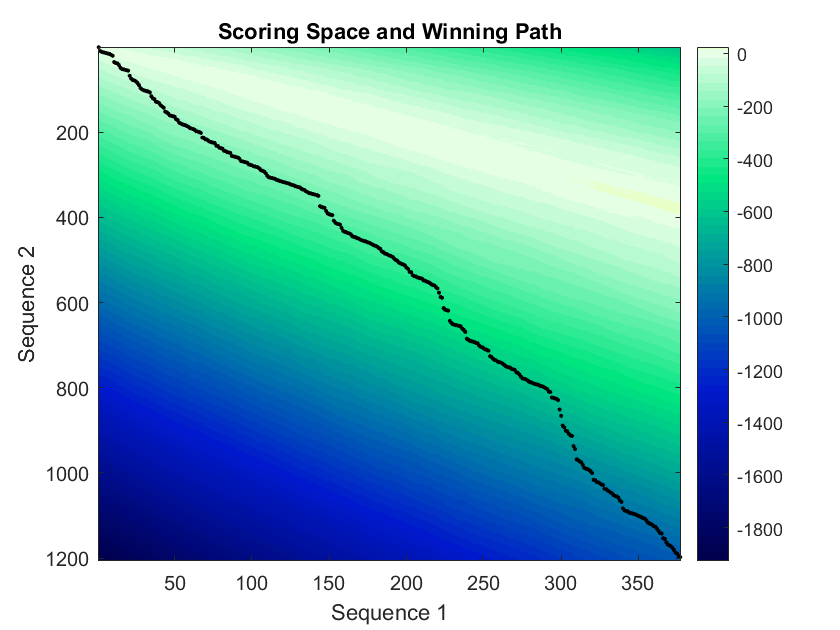

score_global = -1.0216e+03

alignment_global = 3×1206 char array
    'M--------D-GTEIAV-S-P--------------R-SL---H-----S--ELMCP-----------I------C--LD-M---L----K------N--T-MTTK-E--------C----L-H-----RF-C----S--D--C--------I-V--T---ALRS-----G-N-----K-E-CPT-C-R--KKL-V--SKR-S----------LR--PD--P-NFDA-----LI---SKI----YP-SRE------EYEAH--Q----DRVLI---RLS-RLHN--Q---QA-L---S-----S--SIEEG-LR-MQAMHRA-QRV-RRPI--P-GS--D-Q-TTTMSG-G-----------------------E-GEP------G-----E-GEG------------D----G-EDV-------S------S-DS-AP-D----SAP-GP-A-PKRP-RG-G-G-AG-G--S-S-----V-G--TG-G-GG-T---G--G-V---G-G-GA-G----S--E------DS------G-DR-GGTL---GG-GT-L--G-PP---S--P---------P---------G-A-----------------------P---SPP-----------------------E----P--GGEIEL----V--F----R---------------P-H--PLLV-EK----G--EY--C-QT-R------------Y-V---K--TT--GNA-T--V--D-HLS--KYL-----AL---R----I---ALE-R--R-QQ-QEAG-EPG-G-P-G-----GG------------ASDT--G---------------------G--------------P----------------------D---G-------CG-----G---EG-----------------------G------G--------------

[score_global,alignment_global] = nwalign(data_human, data_microalgae,ScoringMatrix='BLOSUM30',Showscore=true)

Another confirmation to use a local allignment is shown by these two figures. Indeed, the second figure, which represents the global allignment, shows an optimal allignment with all negative scores and the score is indeed -1021.6. On the other hand, the first figure, which represents the local allignment, shows a much better score, 53.2. Nevertheless, this score is not very high compared to the allignment of this protein's verions between humans and bearded dragons. This means that a local allignment is possible but that the two proteins are also not very locally similiar.

### **Significance of the local allignment**

Now, to assess the significance of the score obtained for the chosen local alignment, this score is compared to the scores of random sequences, which have the same properties as the protein of the unicellular microalgae, alligned with the human version. Then, an histogram of these scores together with the original score of the local allignment is plotted to show their difference or similiarity. Moreover, to mathematically test significance of the local allignment, a p-value is calculated based on how often the random sequences can be better aligned than the real sequence of the unicellular microalgae. Therefore, it is calculated as


$$p_{\mathrm{value}} =\frac{#\;\mathrm{of}\;\mathrm{scores}\;\mathrm{from}\;\mathrm{alignments}\;\mathrm{with}\;\mathrm{random}\;\mathrm{sequences}\;\mathrm{greater}\;\mathrm{than}\;\mathrm{the}\;\mathrm{original}\;\mathrm{score}}{#\;\mathrm{of}\;\mathrm{runs}}$$


To generate these random sequences with the same features, the function **aacount**, which counts the number of times each amino acid occurs in the original sequence, and the function **randseq**, which generates the sequences based on that distribution, are used. 

runs = 1000;
permutations = char.empty(0,runs);
scores = zeros(1,runs+1);
p_value = 0;
for i = 1:runs
    permutations{i} = randseq(length(data_microalgae),'FromStructure', aacount(data_microalgae));
    scores(i) = swalign(permutations{i}, data_human, ScoringMatrix='BLOSUM30');
    if scores(i)>=score_local
        p_value = p_value+1;
    end
end
p_value = p_value/runs

p_value = 0.0020

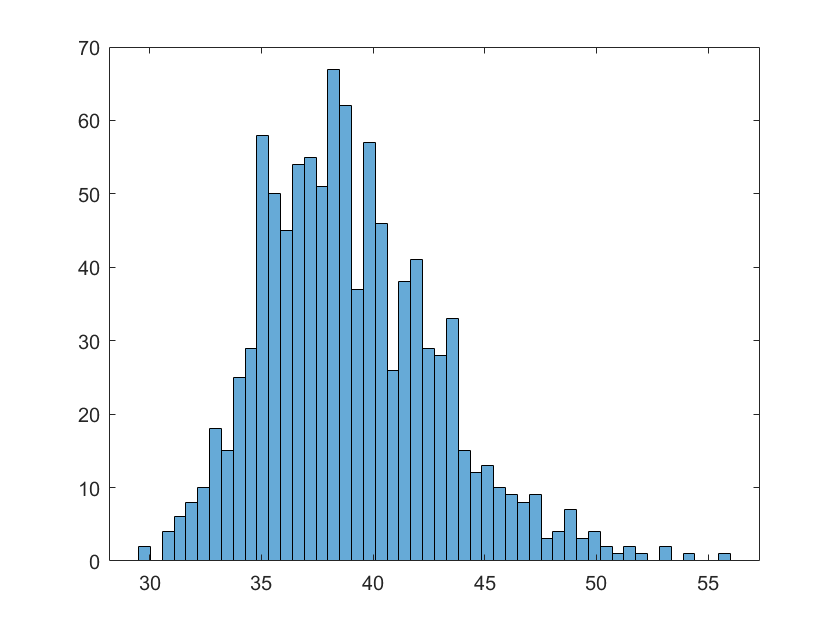

scores(1001) = score_local;
figure
histogram(scores, 50)

Already from the histogram, it is visible that the score of the original local allignment, which is 53.2, is not much different from the scores of the random sequences. This means that the original alignment is similiar to aligning a random sequence with one of the original sequences, which then means that the alignment is not very good. However, considering that the null hypothesis tested by the p-value is that the original score is different than the scores from random sequences, the p-value has a value of 0.002 which is less than 0.05. Therefore, the null hypothesis is rejected and there is a significant difference between the original score and the scores from the random sequences. 

In conlusion, it can be said that they can be considered similiar since there is a significant difference with an alignment with random sequences, however, they are not very close since the length is very different which makes aligning them harder.